## Question Section

In this project, we will consider the question: when do international travel bans need to go into effect in order to reduce the peak infection by 50%?

## Model Section

### Plan

We will use an agent-based SIR model to solve this.  Our model will simulate a population that starts as Susceptible, can be Infected, and can become Recovered.  

We will have one connectivity graph where strongly connected clusters representing countries have weak connections between them (representing international travel).

Once a certain number of global infections (s) is reached, we will cut the weak connections between clusters, representing a 100% effective travel ban between countries.  We will stay in this banned state for the rest of the simulation.

Here are our graphs.

country_population = 10;
number_of_countries = 10;
domestic_connection_weight = 100;
international_connection_weight = 0.001;






function [con_mat] = make_con_mat(country_pop, country_num, dom_weight, int_weight)
    total_pop = country_pop * country_num;

    population_pattern = dom_weight * (ones(country_pop) - eye(country_pop));

    con_mat = ones(total_pop) * int_weight;

    for i = 0:(country_num - 1)
        offset = i * country_pop;
        con_mat(offset + (1:country_pop), offset + (1:country_pop)) = population_pattern;
    end
end

con_mat_wout_bans = make_con_mat(country_population, number_of_countries, domestic_connection_weight, international_connection_weight);

con_mat_w_bans = make_con_mat(country_population, number_of_countries, domestic_connection_weight, 0);


Connectivity Graph Without Bans

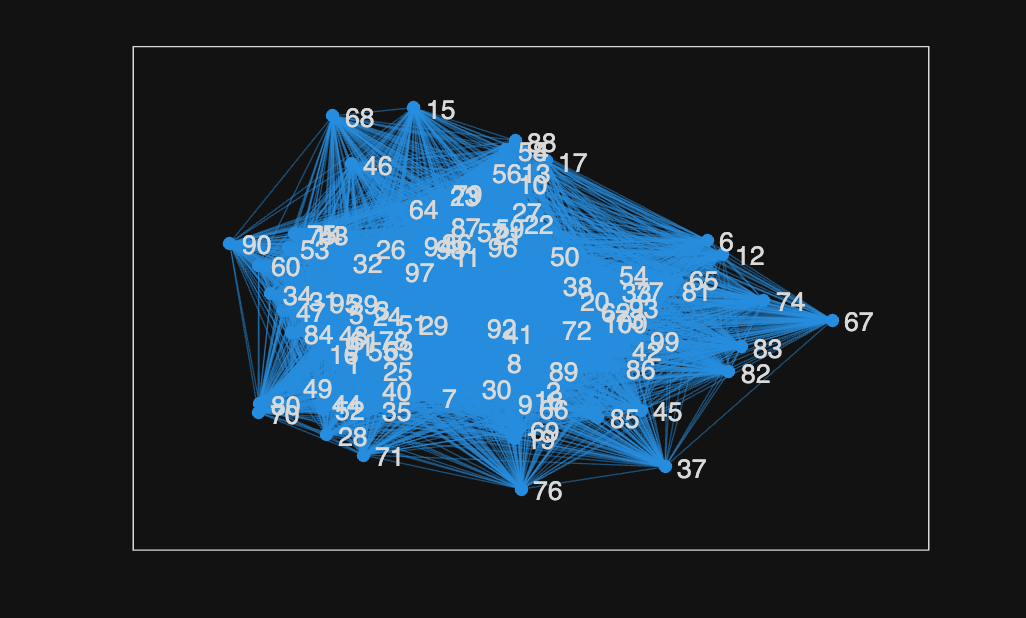

g = graph(con_mat_wout_bans);


plot(g, 'Layout', 'force', 'WeightEffect', 'direct');

Connectivity Graph With Bans

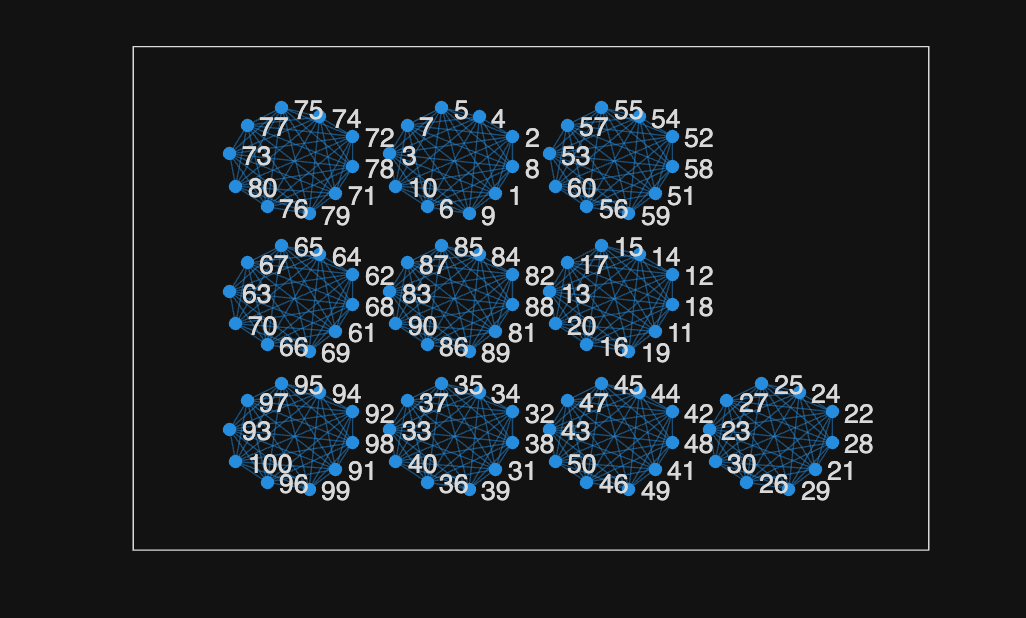

g = graph(con_mat_w_bans);


plot(g, 'Layout', 'force', 'WeightEffect', 'direct');

We will first run the simulation with no travel bans to get a control sample

We will then run the simulation with travel bans, and test different values of s with a parameter sweep, looking at infection peak as our metric

We will select the value of s that creates an infection peak 50% of the control test's infection peak

### Implementation

Implement an SIR_agent_bans() model

Give params for the connectivity graph with bans, connectivity graph with no bans, and when to switch

## Results Section

### Our Number

### Conceptual Validation

Use trends from different country policies from COVID to do this.

## Interpretation Section

### Conclusion

How this can knowledge benefit people